clear ;
close all;

tic
load ryan3_data.mat
toc 

Elapsed time is 1.351235 seconds.


generate_model = true

generate_model = logical
   1


if generate_model == false
    load ryan3_model_Ic_SOH.mat
end

%generate_model = false
% https://kr.mathworks.com/help/matlab/ref/load.html
%load('ryan3_gen_data.mat','battery_dataset')


# 선형회귀 모델 생성

if generate_model
    
tic
mdl_Ic_SOH = fitlm(x_trainValid_Ic_SOH,y_trainValid_SOH)
toc

ryan3_model_Ic_SOH_desc = 'ryan3_model_Ic_SOH_desc';
save('ryan3_model_Ic_SOH.mat','ryan3_model_Ic_SOH_desc')
save('ryan3_model_Ic_SOH.mat','mdl_Ic_SOH')

end

mdl_Ic_SOH = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate        SE         tStat       pValue   
                   _________    _________    _______    ___________

    (Intercept)      0.14119    0.0048375     29.186    3.0881e-185
    x1             -0.054027    0.0071343    -7.5728     3.7342e-14
    x2             0.0054605    0.0090072    0.60623        0.54436
    x3              0.034706    0.0086539     4.0104     6.0722e-05
    x4               0.02765    0.0073434     3.7652     0.00016663
    x5              0.065682    0.0097756     6.7189     1.8565e-11
    x6          

Elapsed time is 0.527142 seconds.


# 선형회귀 예측

coeff = mdl_Ic_SOH.Coefficients.Estimate

coeff =     0.1412
   -0.0540
    0.0055
    0.0347
    0.0276
    0.0657
   -0.0552
   -0.0625
    0.1589
    0.0019


x_trainValid_Ic_SOH(1,:)

ans =     0.4398    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.3625    0.1249    0.1249    0.0124         0         0


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhat = x_trainValid_Ic_SOH*coeff(2:21)+coeff(1)

yhat =     0.9599
    0.9679
    0.9597
    0.9718
    0.9584
    0.9582
    0.9580
    0.9577
    0.9569
    0.9568


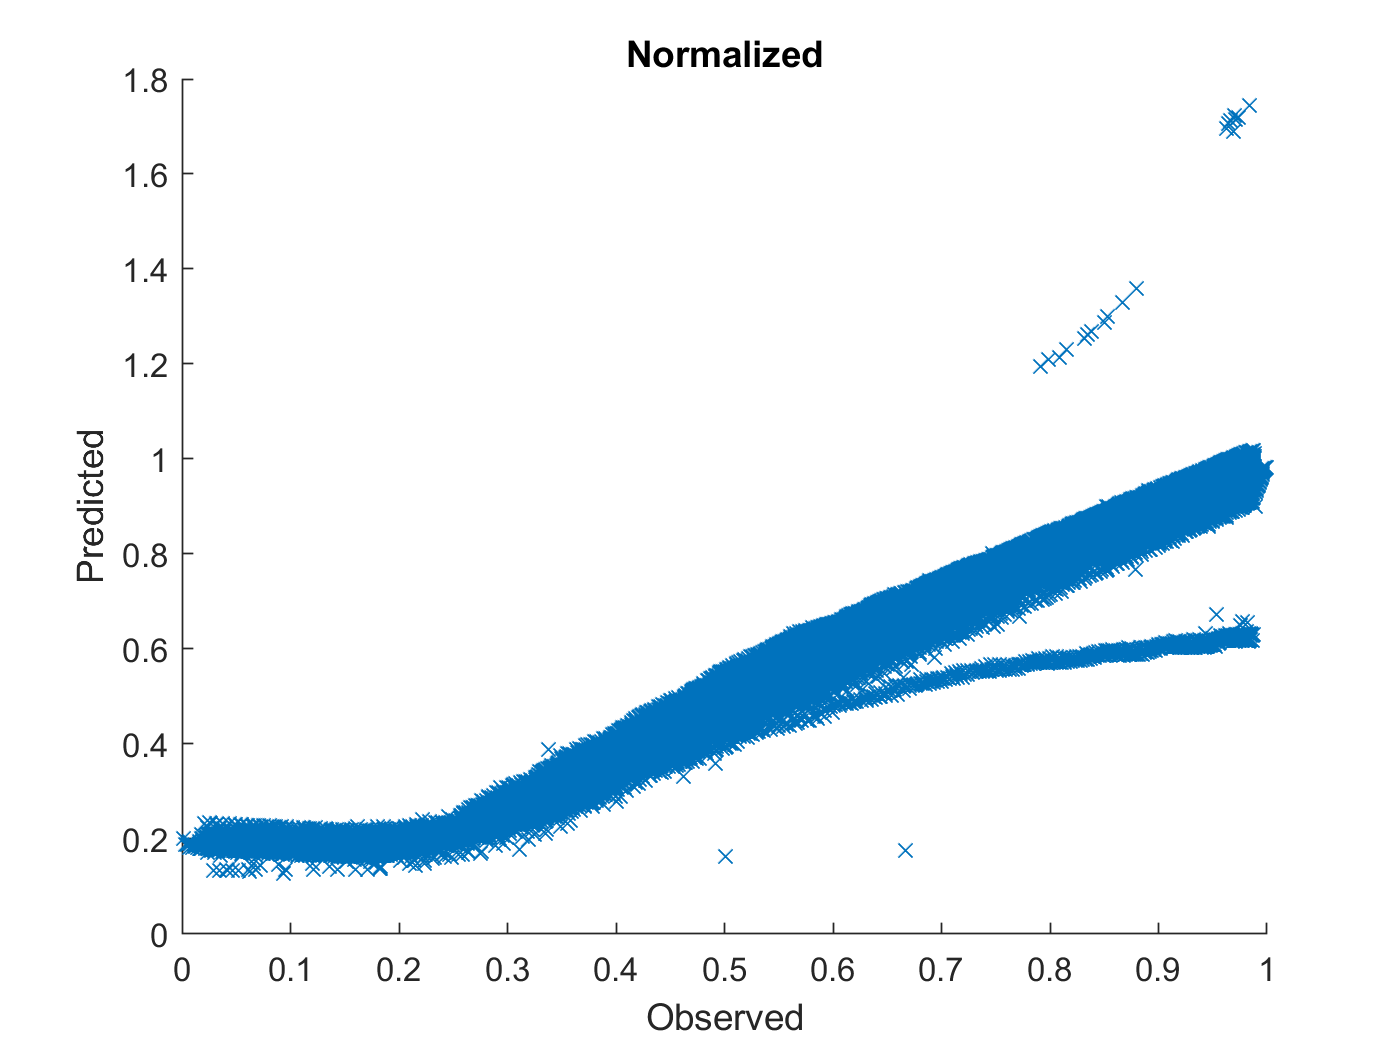

figure
hold on
plot(y_trainValid_SOH,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Normalized'

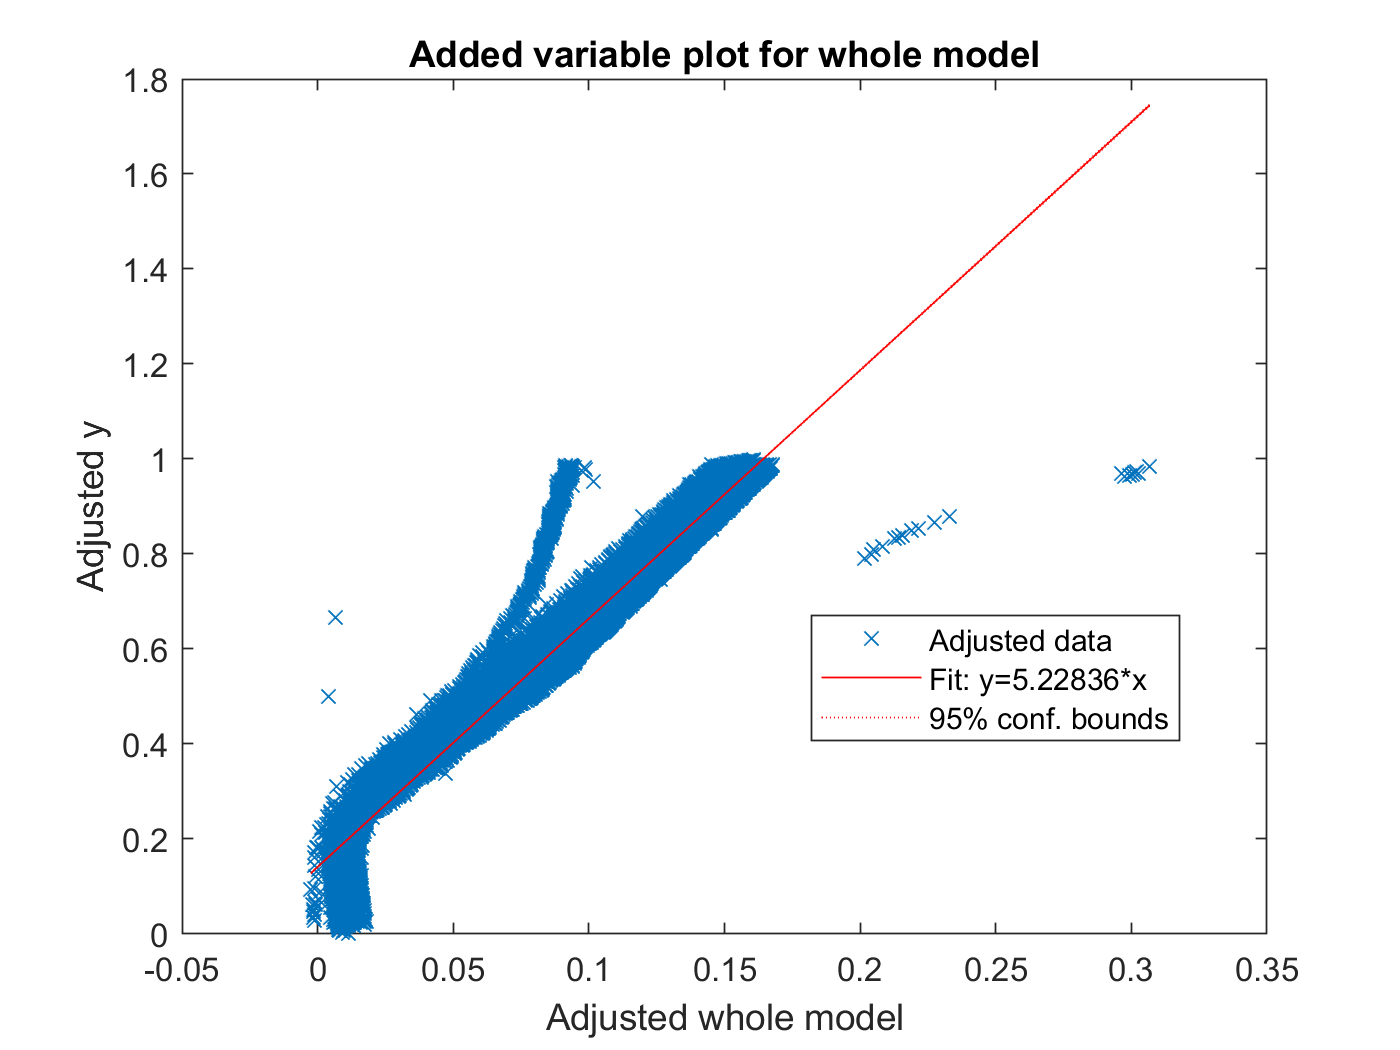


%capHat = Ic(1)

plot(mdl_Ic_SOH)

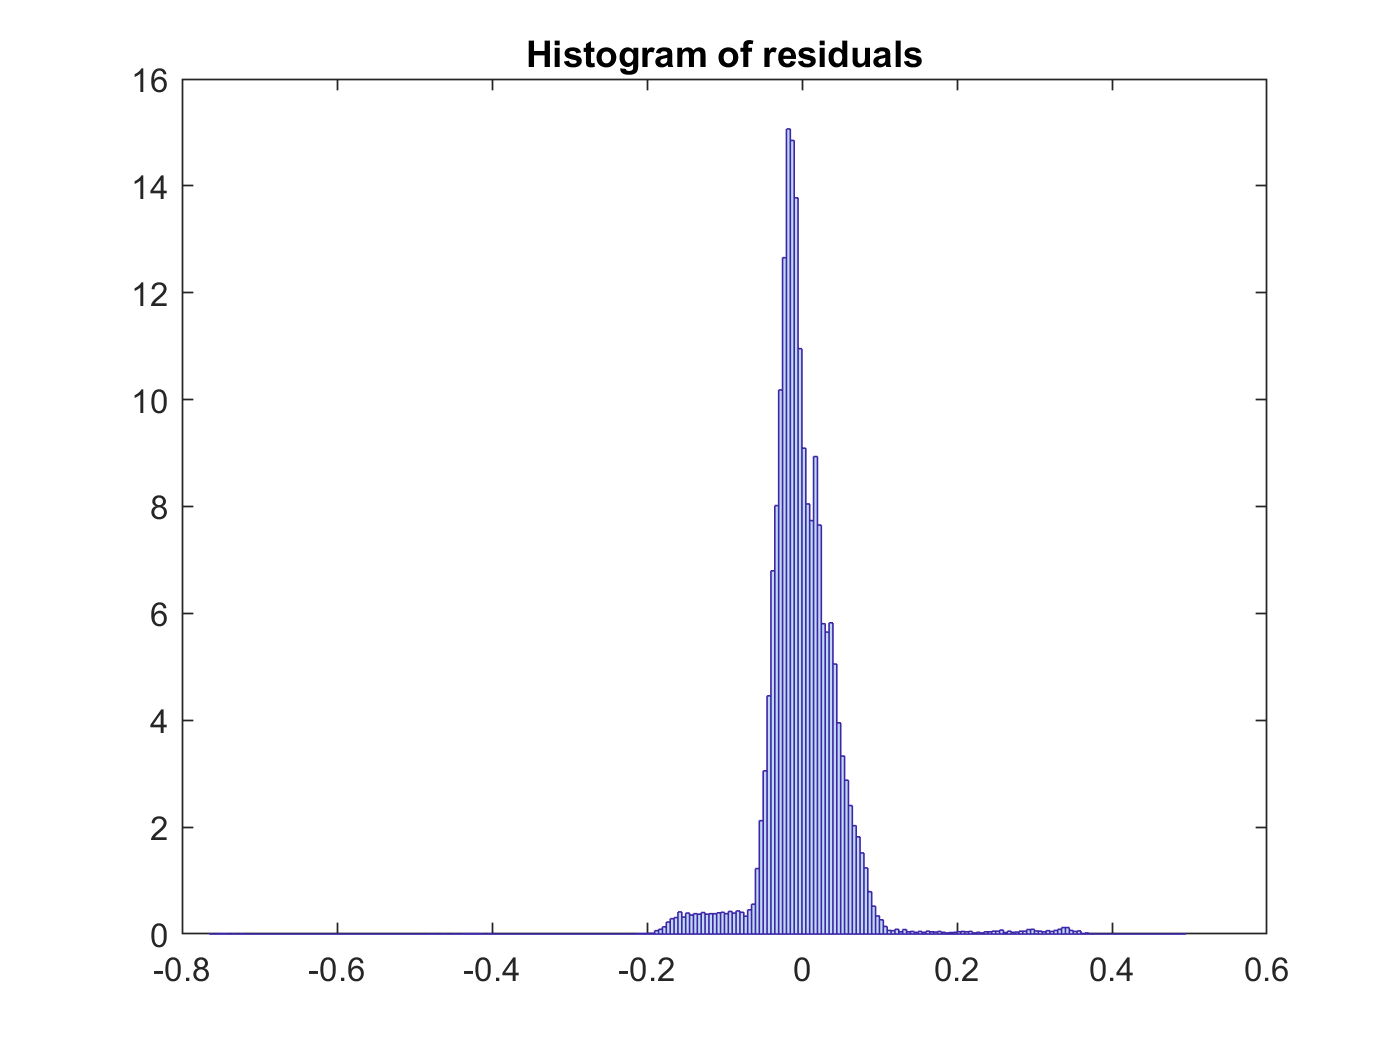

plotResiduals(mdl_Ic_SOH)




% yfit = predict(mdl_Ic_SOH,Ic)
yfit = predict(mdl_Ic_SOH,x_trainValid_Ic_SOH)

yfit =     0.9599
    0.9679
    0.9597
    0.9718
    0.9584
    0.9582
    0.9580
    0.9577
    0.9569
    0.9568


yfit_test = predict(mdl_Ic_SOH,x_test_Ic_SOH)

yfit_test =     0.9764
    0.9757
    0.9753
    0.9742
    0.9740
    0.9737
    0.9727
    0.9718
    0.9706
    0.9688




y= y_trainValid_SOH

y =     0.9878
    0.9872
    0.9867
    0.9861
    0.9855
    0.9849
    0.9843
    0.9837
    0.9832
    0.9826


y_test_SOH

y_test_SOH =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791


# denormaize

yfit = yfit * yrate_SOH + ymin_SOH;
y = y * yrate_SOH + ymin_SOH;
yfit_test = yfit_test * yrate_SOH + ymin_SOH;

MAE = mean(abs(yfit-y))

MAE = 0.0057

adjMAE = MAE/range(y)

adjMAE = 0.0329

range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 0.1734


(y - yhat)    % Errors

ans =     0.0879
    0.0798
    0.0880
    0.0757
    0.0890
    0.0892
    0.0892
    0.0895
    0.0902
    0.0901


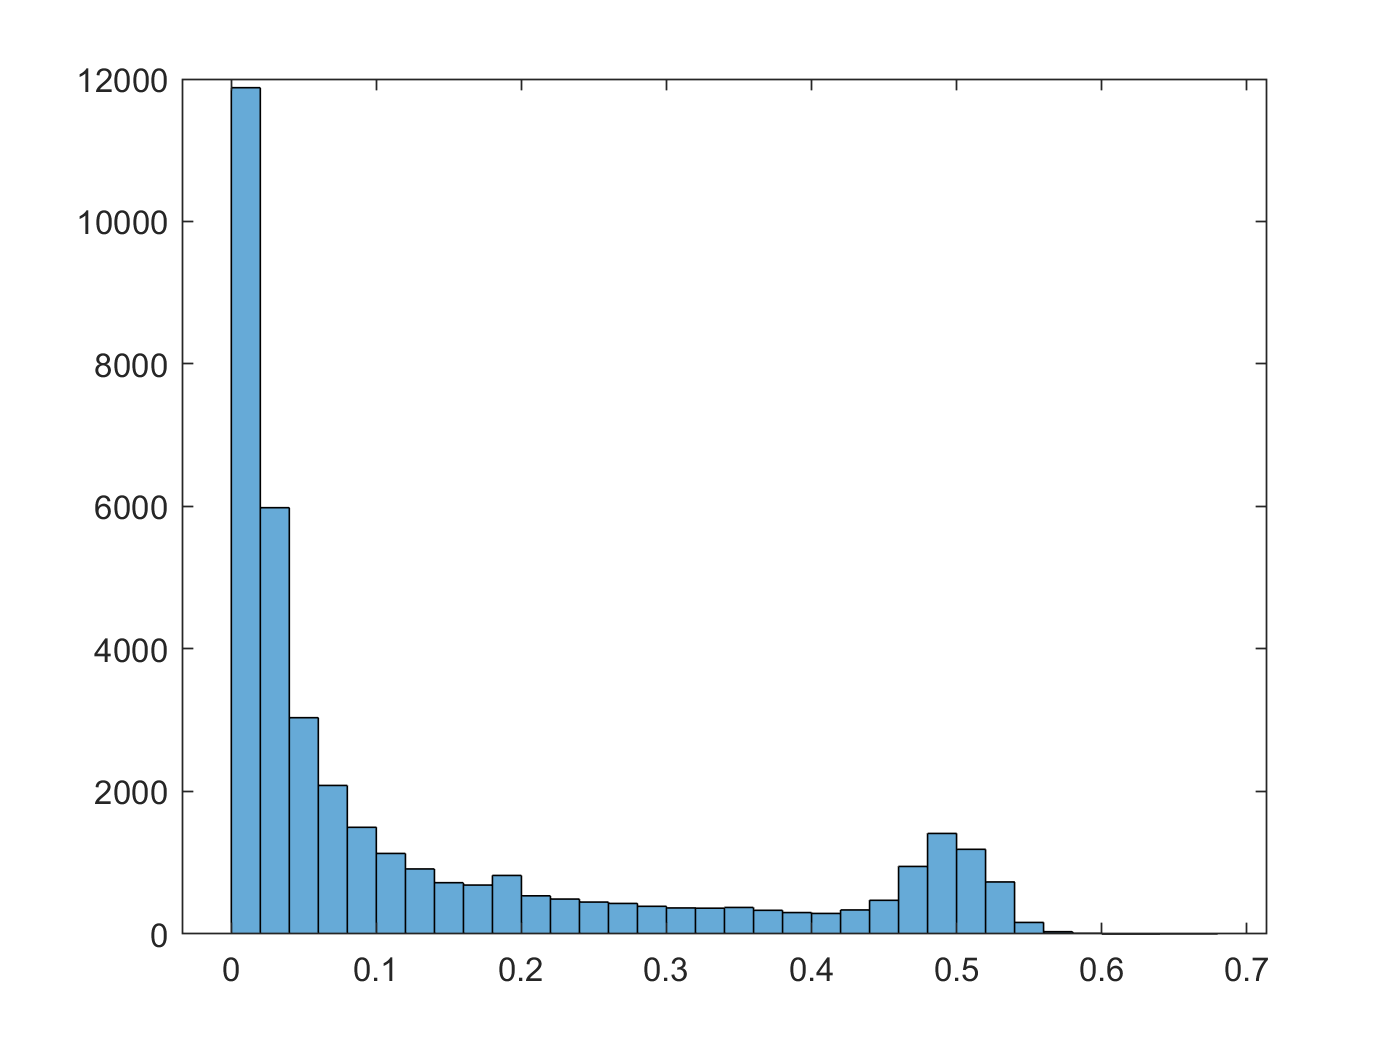

(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 0.3693

y_diff = horzcat(y,(y-yfit))

y_diff =     1.0479    0.0048
    1.0478    0.0034
    1.0477    0.0047
    1.0476    0.0025
    1.0475    0.0047
    1.0474    0.0046
    1.0473    0.0046
    1.0472    0.0045
    1.0471    0.0046
    1.0470    0.0045


y_diff_percentage = abs(y-yfit)./y.*100

y_diff_percentage =     0.4621
    0.3201
    0.4467
    0.2360
    0.4488
    0.4434
    0.4362
    0.4324
    0.4355
    0.4274


length(y_diff_percentage)

ans = 38367

y_diff_percentage_avg = sum(y_diff_percentage)/length(y_diff_percentage)

y_diff_percentage_avg = 0.5852


(Y_test_SOH - yfit_test) 

ans =     0.0018
    0.0018
    0.0017
    0.0018
    0.0017
    0.0015
    0.0016
    0.0016
    0.0016
    0.0018


RMSE_test = sqrt(mean((Y_test_SOH - yfit_test).^2))

RMSE_test = 0.0072

y_diff_test = horzcat(Y_test_SOH,(Y_test_SOH-yfit_test))

y_diff_test =     1.0477    0.0018
    1.0476    0.0018
    1.0474    0.0017
    1.0473    0.0018
    1.0471    0.0017
    1.0470    0.0015
    1.0468    0.0016
    1.0467    0.0016
    1.0465    0.0016
    1.0464    0.0018


y_diff_test_percentage = abs(Y_test_SOH-yfit_test)./Y_test_SOH.*100

y_diff_test_percentage =     0.1751
    0.1712
    0.1643
    0.1682
    0.1578
    0.1472
    0.1499
    0.1509
    0.1554
    0.1703


y_diff_test_percentage_avg = sum(y_diff_test_percentage)/length(y_diff_test_percentage)

y_diff_test_percentage_avg = 0.5641

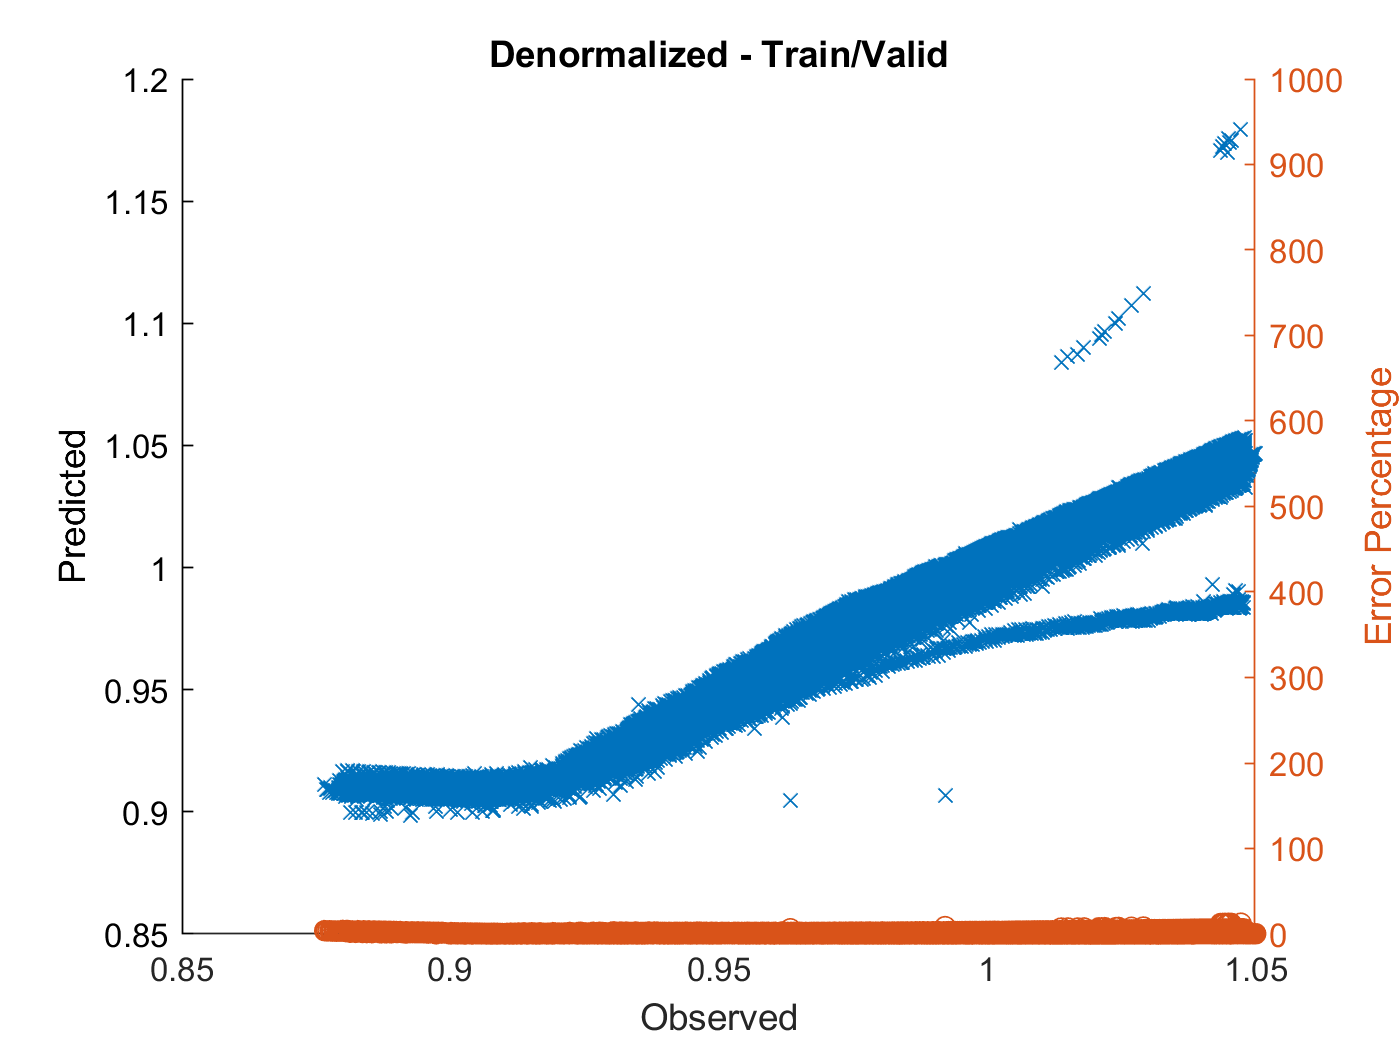


figure
hold on
plot(y,yfit,'x')
xlabel("Observed")
ylabel("Predicted")

yyaxis right
ylabel('Error Percentage')
plot(y,y_diff_percentage,'o');
ylim([0 1000])

hold off
title 'Denormalized - Train/Valid'

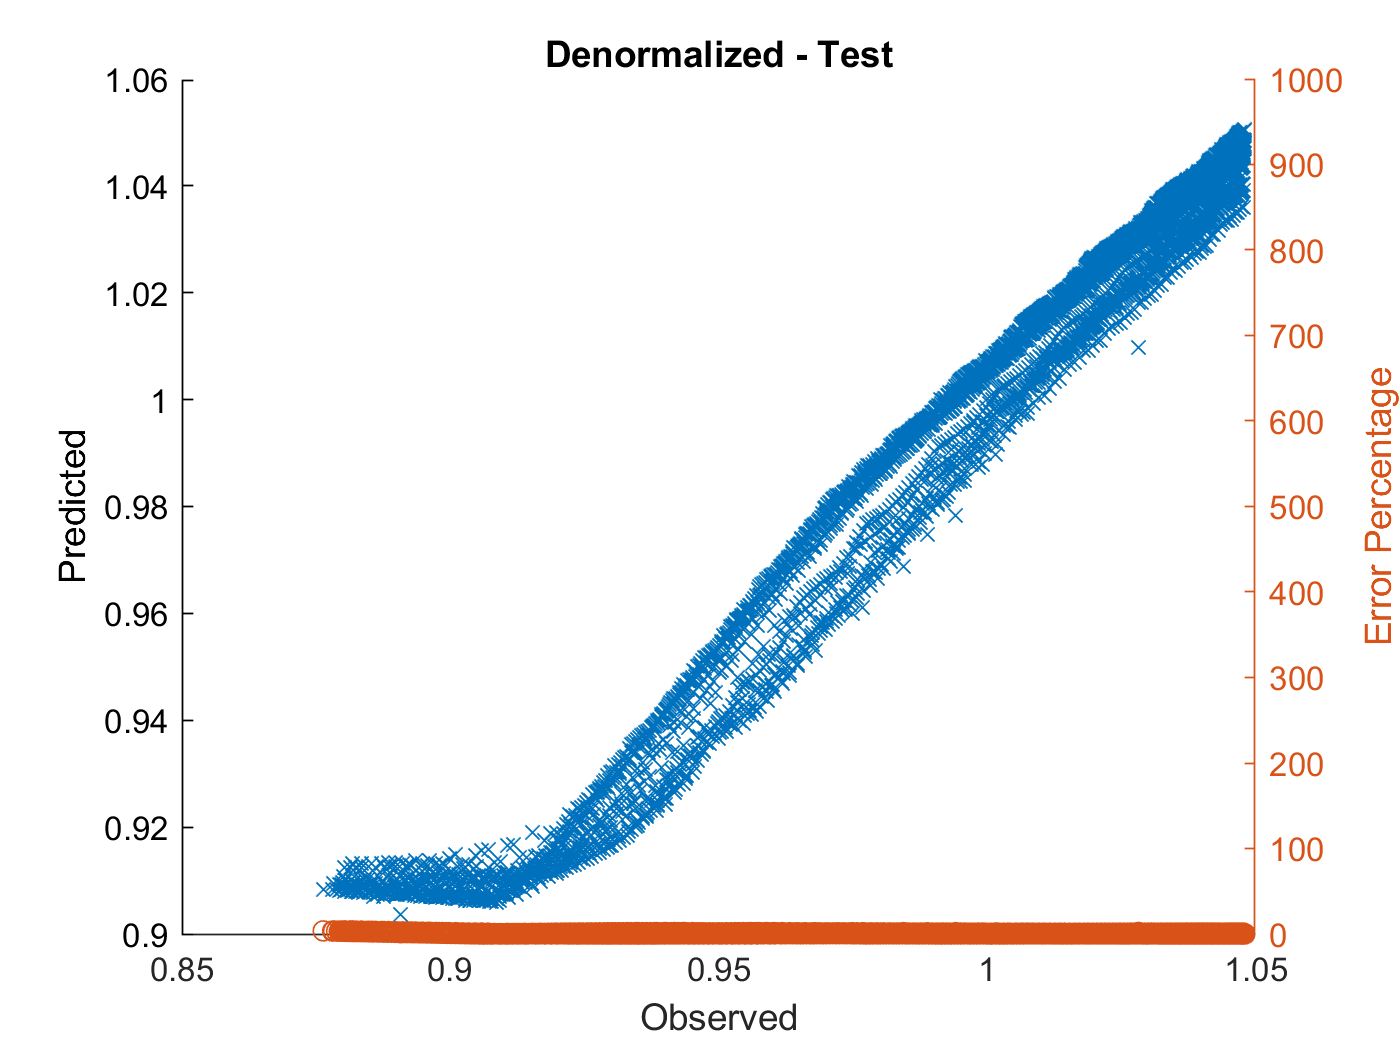


figure
hold on
plot(Y_test_SOH,yfit_test,'x')
xlabel("Observed")
ylabel("Predicted")

yyaxis right
ylabel('Error Percentage')
plot(Y_test_SOH,y_diff_test_percentage,'o');
ylim([0 1000])

hold off
title 'Denormalized - Test'

%xlim([0 1200]), ylim([0 1200])

% 테스트 셋에서는 예측이 전혀 안된다.


# 머신러닝을 위한 기본 설정

epoc_count = 5;
epoc_count_lstm = 3;
%epoc_count = 10; % 시간이 너무 오래 걸린다.
cc_input_size = 20;

# FNN 모델 생성

- FNN1 - 1 layer

if generate_model
netFNN1_1 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_1.divideFcn = 'divideind';
netFNN1_1.divideParam.trainInd = idxTrainAll;
netFNN1_1.divideParam.valInd = idxValidAll;
netFNN1_1.divideParam.testInd = idxTestAll; 
    
%netFNN1__1.divideParam
% https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
netFNN1_1.trainParam.showWindow = 0; 
netFNN1_1.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
[netFNN1_1, tr] = train(netFNN1_1, xnorm_Ic_SOH', ynorm_SOH', 'useparallel',  'yes');
toc
%tr

netFNN1_2 = feedforwardnet(20); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_2.divideFcn = 'divideind';

netFNN1_2.divideFcn = 'divideind';
netFNN1_2.divideParam.trainInd = idxTrainAll;
netFNN1_2.divideParam.valInd = idxValidAll;
netFNN1_2.divideParam.testInd = idxTestAll; 
    
%netFNN1_2.divideParam
netFNN1_2.trainParam.showWindow = 0; 
netFNN1_2.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
netFNN1_2 = train(netFNN1_2, xnorm_Ic_SOH', ynorm_SOH', 'useparallel',  'yes');
toc


netFNN1_3 = feedforwardnet(100); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_3.divideFcn = 'divideind';

netFNN1_3.divideFcn = 'divideind';
netFNN1_3.divideParam.trainInd = idxTrainAll;
netFNN1_3.divideParam.valInd = idxValidAll;
netFNN1_3.divideParam.testInd = idxTestAll; 
    
%netFNN1_3.divideParam
netFNN1_3.trainParam.showWindow = 0; 
netFNN1_3.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
netFNN1_3 = train(netFNN1_3, xnorm_Ic_SOH', ynorm_SOH', 'useparallel',  'yes');
toc


netFNN2_1 = feedforwardnet([20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_1.divideParam.trainInd = idxTrainAll;
netFNN2_1.divideParam.valInd = idxValidAll;
netFNN2_1.divideParam.testInd = idxTestAll; 

netFNN2_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_1.trainParam.showWindow = 0;
netFNN2_1.trainParam.show = NaN;
tic
[netFNN2_1, tr2] = train(netFNN2_1, xnorm_Ic_SOH', ynorm_SOH', 'useparallel',  'yes');
toc
%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN2_2 = feedforwardnet([50,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_2.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_2.divideParam.trainInd = idxTrainAll;
netFNN2_2.divideParam.valInd = idxValidAll;
netFNN2_2.divideParam.testInd = idxTestAll; 

netFNN2_2.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_2.trainParam.show = NaN;
netFNN2_2.trainParam.showWindow = 0;
tic
netFNN2_2 = train(netFNN2_1, xnorm_Ic_SOH', ynorm_SOH', 'useparallel',  'yes');
toc
%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN3_1 = feedforwardnet([50,20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN3_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN3_1.divideParam.trainInd = idxTrainAll;
netFNN3_1.divideParam.valInd = idxValidAll;
netFNN3_1.divideParam.testInd = idxTestAll; 

netFNN3_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN3_1.trainParam.show = NaN;
netFNN3_1.trainParam.showWindow = 0;
tic
netFNN3_1 = train(netFNN3_1, xnorm_Ic_SOH', ynorm_SOH', 'useparallel',  'yes');
toc
%view(netFNN3_1)


netFNN4_1 = feedforwardnet([50,20,10,5]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN4_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN4_1.divideParam.trainInd = idxTrainAll;
netFNN4_1.divideParam.valInd = idxValidAll;
netFNN4_1.divideParam.testInd = idxTestAll; 

netFNN4_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN4_1.trainParam.show = NaN;
netFNN4_1.trainParam.showWindow = 0;
tic
netFNN4_1 = train(netFNN4_1, xnorm_Ic_SOH', ynorm_SOH', 'useparallel',  'yes');
toc
%view(netFNN3_1)


netFNN5_1 = feedforwardnet([50,20,10,5,5]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN5_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN5_1.divideParam.trainInd = idxTrainAll;
netFNN5_1.divideParam.valInd = idxValidAll;
netFNN5_1.divideParam.testInd = idxTestAll; 

netFNN5_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN5_1.trainParam.show = NaN;
netFNN5_1.trainParam.showWindow = 0;
tic
netFNN5_1 = train(netFNN5_1, xnorm_Ic_SOH', ynorm_SOH', 'useparallel',  'yes');
toc
%view(netFNN3_1)


save('ryan3_model_Ic_SOH.mat','netFNN1_1' ,'-append')
save('ryan3_model_Ic_SOH.mat','netFNN1_2' ,'-append')
save('ryan3_model_Ic_SOH.mat','netFNN1_3' ,'-append')
save('ryan3_model_Ic_SOH.mat','netFNN2_1' ,'-append')
save('ryan3_model_Ic_SOH.mat','netFNN2_2' ,'-append')
save('ryan3_model_Ic_SOH.mat','netFNN3_1' ,'-append')
save('ryan3_model_Ic_SOH.mat','netFNN4_1' ,'-append')
save('ryan3_model_Ic_SOH.mat','netFNN5_1' ,'-append')

end

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 1.147622 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 1.928564 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 46.579706 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 4.131422 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 4.499783 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 52.231499 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 132.899996 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 219.979647 seconds.


# FNN 예측


pFNN1_1 = netFNN1_1(xnorm_Ic_SOH(idxTestAll, :)');
pFNN1_2 = netFNN1_2(xnorm_Ic_SOH(idxTestAll, :)');
pFNN1_3 = netFNN1_3(xnorm_Ic_SOH(idxTestAll, :)');
pFNN2_1 = netFNN2_1(xnorm_Ic_SOH(idxTestAll, :)');
pFNN2_2 = netFNN2_2(xnorm_Ic_SOH(idxTestAll, :)');
pFNN3_1 = netFNN3_1(xnorm_Ic_SOH(idxTestAll, :)');
pFNN4_1 = netFNN4_1(xnorm_Ic_SOH(idxTestAll, :)');
pFNN5_1 = netFNN5_1(xnorm_Ic_SOH(idxTestAll, :)');

ytest = ynorm_SOH(idxTestAll, :)*yrate_SOH + ymin_SOH;
pFNN1_1_hat = pFNN1_1 * yrate_SOH + ymin_SOH;
pFNN1_2_hat = pFNN1_2 * yrate_SOH + ymin_SOH;
pFNN1_3_hat = pFNN1_3 * yrate_SOH + ymin_SOH;
pFNN2_1_hat = pFNN2_1 * yrate_SOH + ymin_SOH;
pFNN2_2_hat = pFNN2_2 * yrate_SOH + ymin_SOH;
pFNN3_1_hat = pFNN3_1 * yrate_SOH + ymin_SOH;
pFNN4_1_hat = pFNN4_1 * yrate_SOH + ymin_SOH;
pFNN5_1_hat = pFNN5_1 * yrate_SOH + ymin_SOH;


rmse_pFNN1_1_hat = sqrt(mean(( ytest' - pFNN1_1_hat ).^2))

rmse_pFNN1_1_hat = 0.0090

rmse_pFNN1_2_hat = sqrt(mean(( ytest' - pFNN1_2_hat ).^2))

rmse_pFNN1_2_hat = 0.0023

rmse_pFNN1_3_hat = sqrt(mean(( ytest' - pFNN1_3_hat ).^2))

rmse_pFNN1_3_hat = 0.0022

rmse_pFNN2_1_hat = sqrt(mean(( ytest' - pFNN2_1_hat ).^2))

rmse_pFNN2_1_hat = 0.0031

rmse_pFNN2_2_hat = sqrt(mean(( ytest' - pFNN2_2_hat ).^2))

rmse_pFNN2_2_hat = 0.0022

rmse_pFNN3_1_hat = sqrt(mean(( ytest' - pFNN3_1_hat ).^2))

rmse_pFNN3_1_hat = 0.0015

rmse_pFNN4_1_hat = sqrt(mean(( ytest' - pFNN4_1_hat ).^2))

rmse_pFNN4_1_hat = 0.0076

rmse_pFNN5_1_hat = sqrt(mean(( ytest' - pFNN5_1_hat ).^2))

rmse_pFNN5_1_hat = 0.0128



y_test_diff_percentage_FNN1_1_hat_avg = sum(abs(Y_test_SOH'-pFNN1_1_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN1_1_hat)./Y_test_SOH')

y_test_diff_percentage_FNN1_1_hat_avg = 0.6271

y_test_diff_percentage_FNN1_2_hat_avg = sum(abs(Y_test_SOH'-pFNN1_2_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN1_2_hat)./Y_test_SOH')

y_test_diff_percentage_FNN1_2_hat_avg = 0.1732

y_test_diff_percentage_FNN1_3_hat_avg = sum(abs(Y_test_SOH'-pFNN1_3_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN1_3_hat)./Y_test_SOH')

y_test_diff_percentage_FNN1_3_hat_avg = 0.1739

y_test_diff_percentage_FNN2_1_hat_avg = sum(abs(Y_test_SOH'-pFNN2_1_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN2_1_hat)./Y_test_SOH')

y_test_diff_percentage_FNN2_1_hat_avg = 0.2238

y_test_diff_percentage_FNN2_2_hat_avg = sum(abs(Y_test_SOH'-pFNN2_2_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN2_2_hat)./Y_test_SOH')

y_test_diff_percentage_FNN2_2_hat_avg = 0.1619

y_test_diff_percentage_FNN3_1_hat_avg = sum(abs(Y_test_SOH'-pFNN3_1_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN3_1_hat)./Y_test_SOH')

y_test_diff_percentage_FNN3_1_hat_avg = 0.1183

y_test_diff_percentage_FNN4_1_hat_avg = sum(abs(Y_test_SOH'-pFNN4_1_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN4_1_hat)./Y_test_SOH')

y_test_diff_percentage_FNN4_1_hat_avg = 0.6326

y_test_diff_percentage_FNN5_1_hat_avg = sum(abs(Y_test_SOH'-pFNN5_1_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN5_1_hat)./Y_test_SOH')

y_test_diff_percentage_FNN5_1_hat_avg = 0.8459

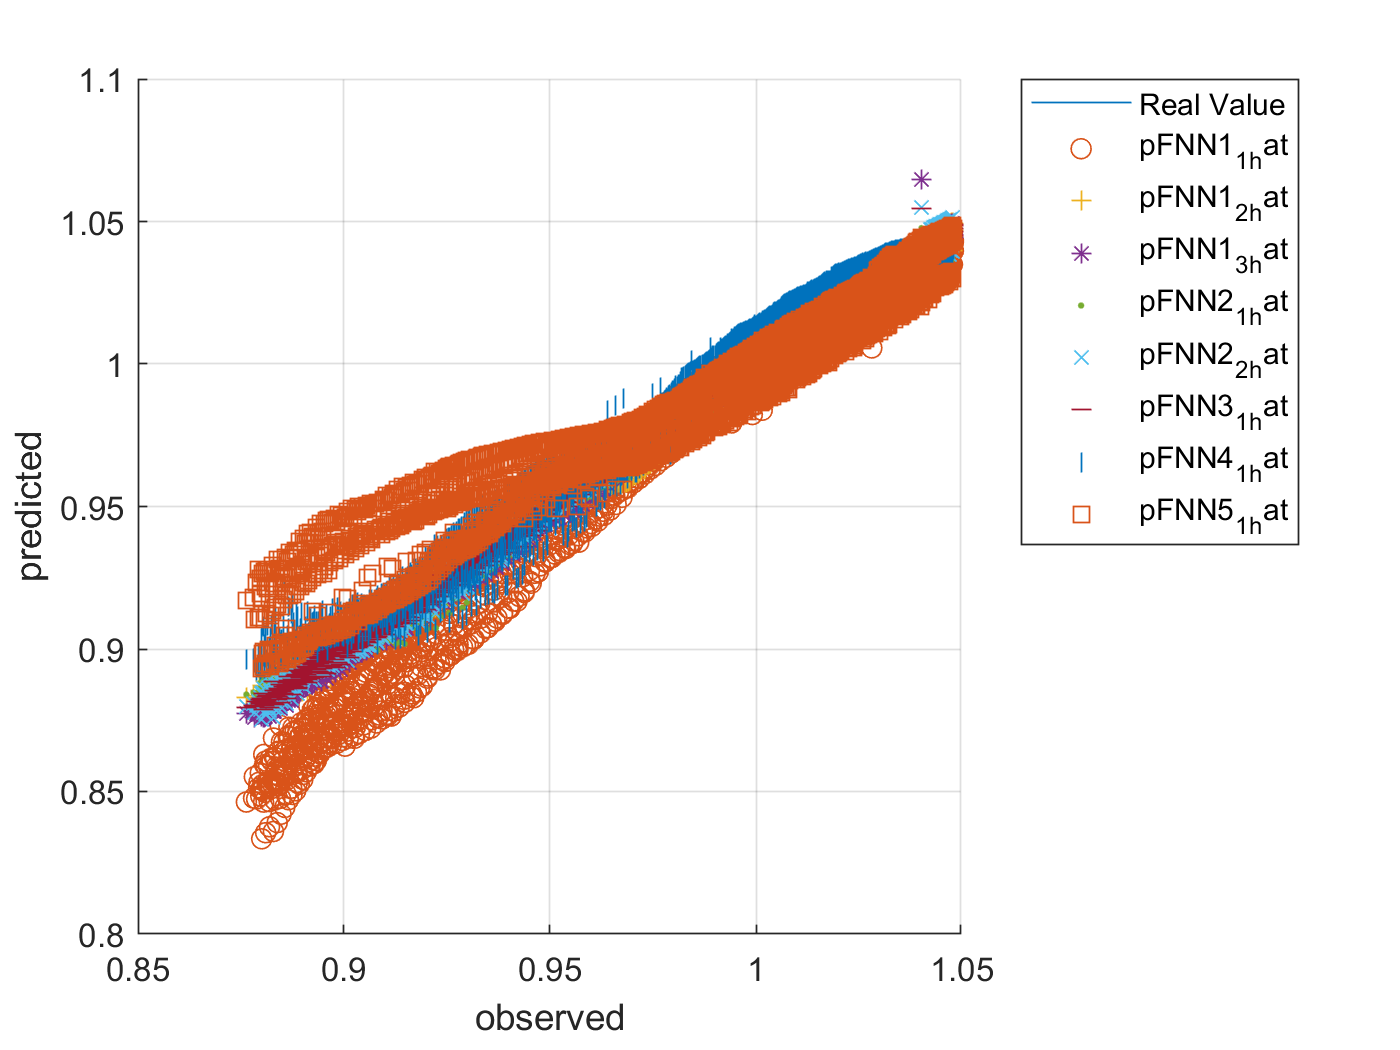



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_1_hat,'o')
plot(ytest,pFNN1_2_hat,'+')
plot(ytest,pFNN1_3_hat,'*')
plot(ytest,pFNN2_1_hat,'.')
plot(ytest,pFNN2_2_hat,'x')
plot(ytest,pFNN3_1_hat,'_')
plot(ytest,pFNN4_1_hat,'|')
plot(ytest,pFNN5_1_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_hat', ... 
		'pFNN1_2_hat', ...
		'pFNN1_3_hat', ... 	
		'pFNN2_1_hat', ... 
		'pFNN2_2_hat', ... 
		'pFNN3_1_hat', ... 
		'pFNN4_1_hat', ... 
		'pFNN5_1_hat','Location','northeastoutside')


y_test_diff_percentage_FNN1_2_hat = abs(Y_test_SOH'-pFNN1_2_hat)./Y_test_SOH'.*100

y_test_diff_percentage_FNN1_2_hat =     0.1760    0.1845    0.1947    0.1992    0.2105    0.2227    0.2257    0.2250    0.2207    0.2101    0.2071    0.2098    0.2016    0.2130    0.2345    0.2338    0.1951    0.2126    0.1910    0.1817    0.1668    0.2280    0.2922    0.3327    0.3481    0.3591    0.3569    0.3336    0.2905    0.2102    0.1477    0.1541    0.1385    0.1434    0.1421    0.1457    0.1390    0.1593    0.1576    0.1719    0.1851    0.1793    0.1935    0.2010    0.2081    0.2153    0.2278    0.2380    0.2312    0.2543


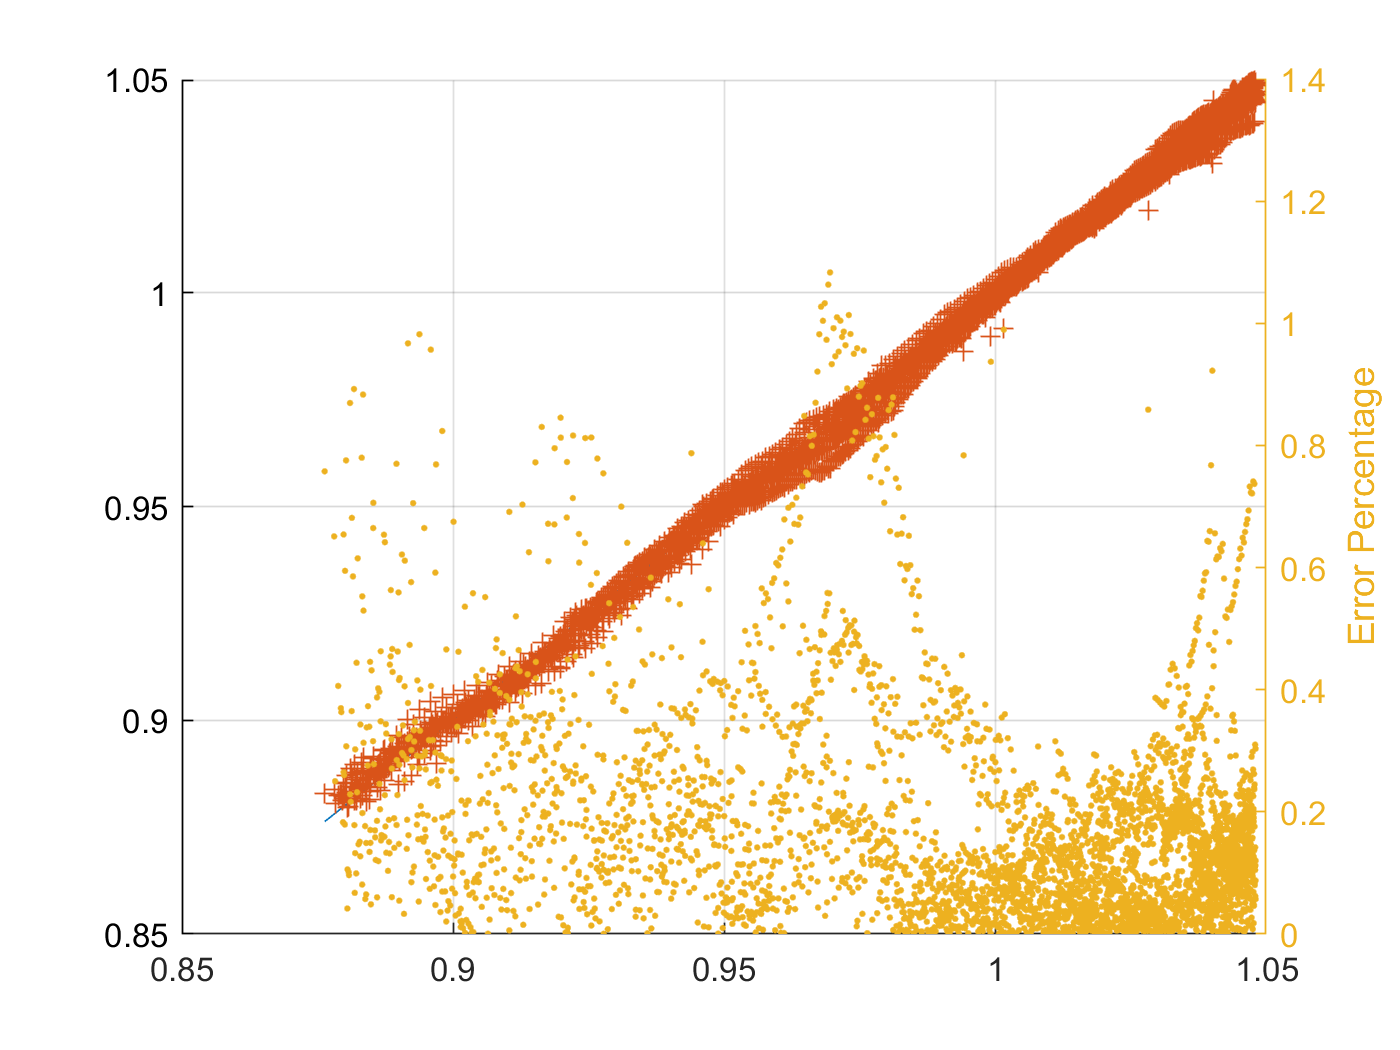

figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_2_hat,'+')

yyaxis right
ylabel('Error Percentage')
plot(ytest,y_test_diff_percentage_FNN1_2_hat,'.')

hold off

pFNN1_1_self = netFNN1_1(xnorm_Ic_SOH([idxTrainAll idxValidAll], :)');
pFNN1_2_self = netFNN1_2(xnorm_Ic_SOH([idxTrainAll idxValidAll], :)');
pFNN1_3_self = netFNN1_3(xnorm_Ic_SOH([idxTrainAll idxValidAll], :)');
pFNN2_1_self = netFNN2_1(xnorm_Ic_SOH([idxTrainAll idxValidAll], :)');
pFNN2_2_self = netFNN2_2(xnorm_Ic_SOH([idxTrainAll idxValidAll], :)');
pFNN3_1_self = netFNN3_1(xnorm_Ic_SOH([idxTrainAll idxValidAll], :)');
pFNN4_1_self = netFNN4_1(xnorm_Ic_SOH([idxTrainAll idxValidAll], :)');
pFNN5_1_self = netFNN5_1(xnorm_Ic_SOH([idxTrainAll idxValidAll], :)');

ytrain_self = ynorm_SOH([idxTrainAll idxValidAll], :)*yrate_SOH + ymin_SOH;
pFNN1_1_self_hat = pFNN1_1_self * yrate_SOH + ymin_SOH;
pFNN1_2_self_hat = pFNN1_2_self * yrate_SOH + ymin_SOH;
pFNN1_3_self_hat = pFNN1_3_self * yrate_SOH + ymin_SOH;
pFNN2_1_self_hat = pFNN2_1_self * yrate_SOH + ymin_SOH;
pFNN2_2_self_hat = pFNN2_2_self * yrate_SOH + ymin_SOH;
pFNN3_1_self_hat = pFNN3_1_self * yrate_SOH + ymin_SOH;
pFNN4_1_self_hat = pFNN4_1_self * yrate_SOH + ymin_SOH;
pFNN5_1_self_hat = pFNN5_1_self * yrate_SOH + ymin_SOH;


rmse_pFNN1_1_self_hat = sqrt(mean(( ytrain_self' - pFNN1_1_self_hat ).^2))

rmse_pFNN1_1_self_hat = 0.0094

rmse_pFNN1_2_self_hat = sqrt(mean(( ytrain_self' - pFNN1_2_self_hat ).^2))

rmse_pFNN1_2_self_hat = 0.0027

rmse_pFNN1_3_self_hat = sqrt(mean(( ytrain_self' - pFNN1_3_self_hat ).^2))

rmse_pFNN1_3_self_hat = 0.0024

rmse_pFNN2_1_self_hat = sqrt(mean(( ytrain_self' - pFNN2_1_self_hat ).^2))

rmse_pFNN2_1_self_hat = 0.0037

rmse_pFNN2_2_self_hat = sqrt(mean(( ytrain_self' - pFNN2_2_self_hat ).^2))

rmse_pFNN2_2_self_hat = 0.0027

rmse_pFNN3_1_self_hat = sqrt(mean(( ytrain_self' - pFNN3_1_self_hat ).^2))

rmse_pFNN3_1_self_hat = 0.0022

rmse_pFNN4_1_self_hat = sqrt(mean(( ytrain_self' - pFNN4_1_self_hat ).^2))

rmse_pFNN4_1_self_hat = 0.0077

rmse_pFNN5_1_self_hat = sqrt(mean(( ytrain_self' - pFNN5_1_self_hat ).^2))

rmse_pFNN5_1_self_hat = 0.0112

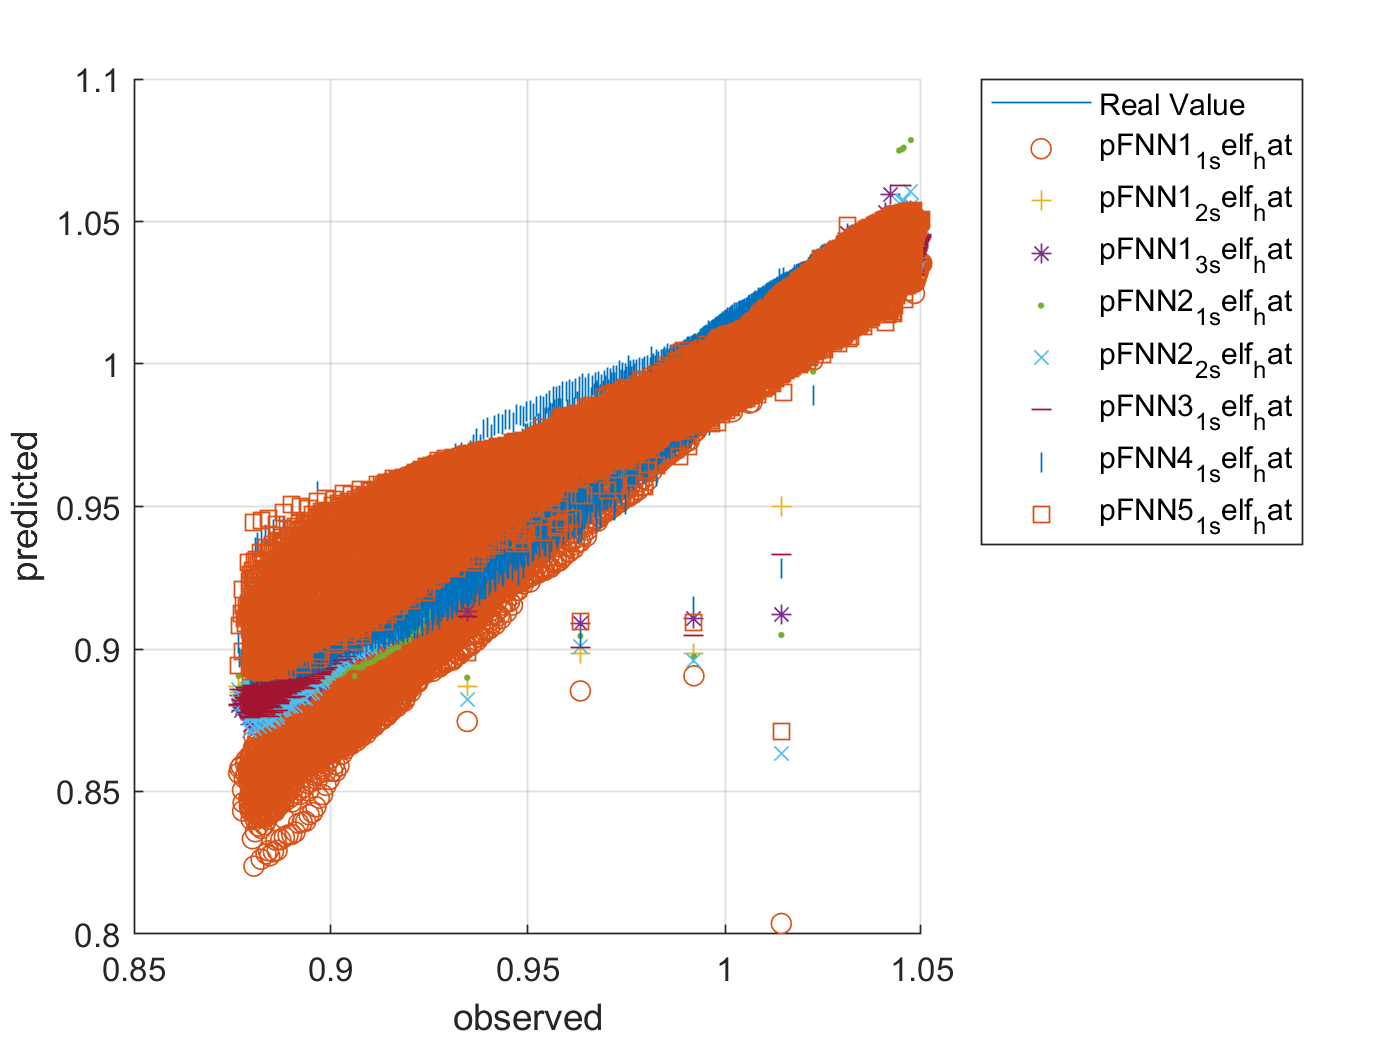



figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pFNN1_1_self_hat,'o')
plot(ytrain_self,pFNN1_2_self_hat,'+')
plot(ytrain_self,pFNN1_3_self_hat,'*')
plot(ytrain_self,pFNN2_1_self_hat,'.')
plot(ytrain_self,pFNN2_2_self_hat,'x')
plot(ytrain_self,pFNN3_1_self_hat,'_')
plot(ytrain_self,pFNN4_1_self_hat,'|')
plot(ytrain_self,pFNN5_1_self_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_self_hat', ... 
		'pFNN1_2_self_hat', ...
		'pFNN1_3_self_hat', ... 	
		'pFNN2_1_self_hat', ... 
		'pFNN2_2_self_hat', ... 
		'pFNN3_1_self_hat', ... 
		'pFNN4_1_self_hat', ... 
		'pFNN5_1_self_hat','Location','northeastoutside')

# CNN

% For CNN
filterSize = 3;
numFilters = 32;
numFCN = 1;


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.


if generate_model

layerCNN2_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
cellx = num2cell(xnorm_Ic_SOH', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm_SOH);
tbl = table(cellx);
tbl.cellyB = cellyB;


Traintbl = tbl(idxTrainAll, :);
valtbl = tbl(idxValidAll, :);
testtbl = tbl(idxTestAll, :);

options = trainingOptions('adam', ...
 'InitialLearnRate', 0.001, ...
 'MaxEpochs',epoc_count, ...
 'MiniBatchSize',50, ...
 'Plots','training-progress', 'ValidationData', valtbl);

tic
netCNN2_1 = trainNetwork(Traintbl, layerCNN2_1, options);
toc




- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:29 |         0.72 |         0.72 |       0.2557 |       0.2566 |          0.0010 |
|       1 |          50 |       00:00:43 |         0.26 |         0.23 |       0.0337 |       0.0271 |          0.0010 |
|       1 |         100 |       00:01:00 |         0.22 |         0.19 |       0.0243 |       0.0173 |          0.0010 |
|       1 |         150 |       00:01:16 |         0.17 |         0.15 |       0.0146 |   

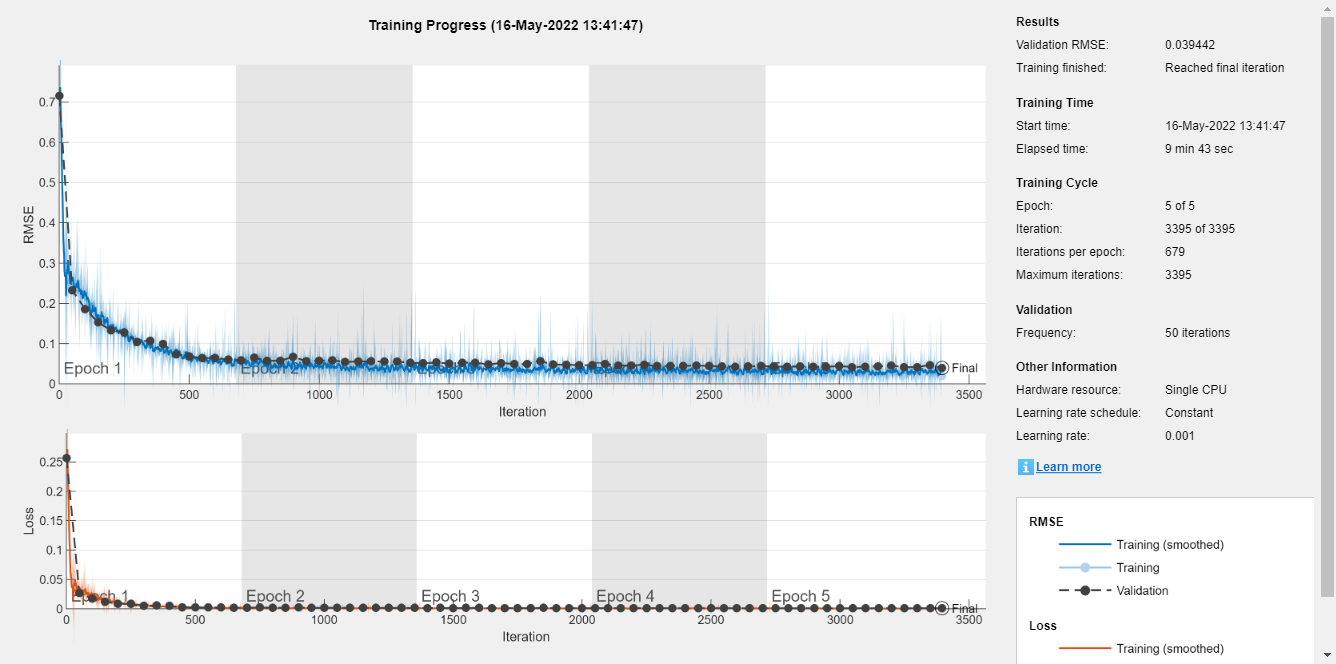

Elapsed time is 670.765925 seconds.


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |         0.82 |         0.75 |       0.3335 |       0.2844 |          0.0010 |
|       1 |          50 |       00:00:17 |         0.25 |         0.22 |       0.0306 |       0.0244 |          0.0010 |
|       1 |         100 |       00:00:23 |         0.25 |         0.19 |       0.0303 |       0.0178 |          0.0010 |
|       1 |         150 |       00:00:28 |         0.19 |         0.16 |       0.0176 |   

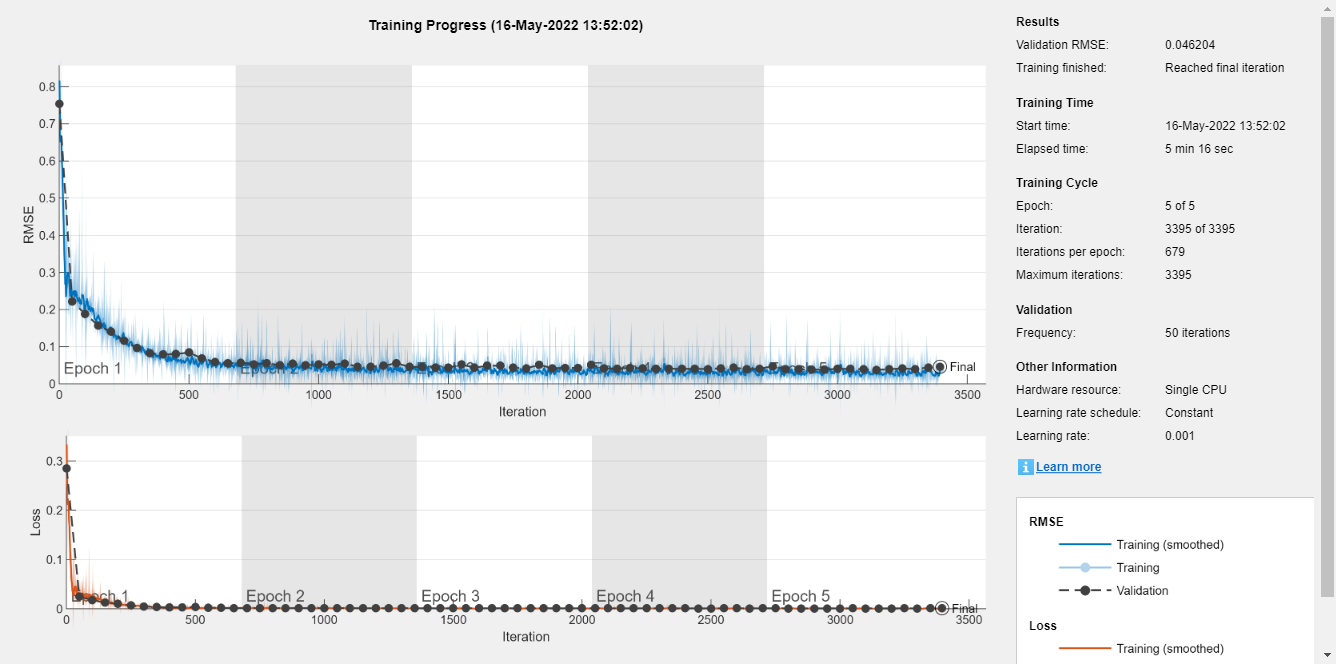

Elapsed time is 345.921647 seconds.


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |         0.69 |         0.66 |       0.2411 |       0.2157 |          0.0010 |
|       1 |          50 |       00:00:13 |         0.29 |         0.25 |       0.0425 |       0.0306 |          0.0010 |
|       1 |         100 |       00:00:16 |         0.24 |         0.20 |       0.0289 |       0.0206 |          0.0010 |
|       1 |         150 |       00:00:22 |         0.21 |         0.17 |       0.0215 |   

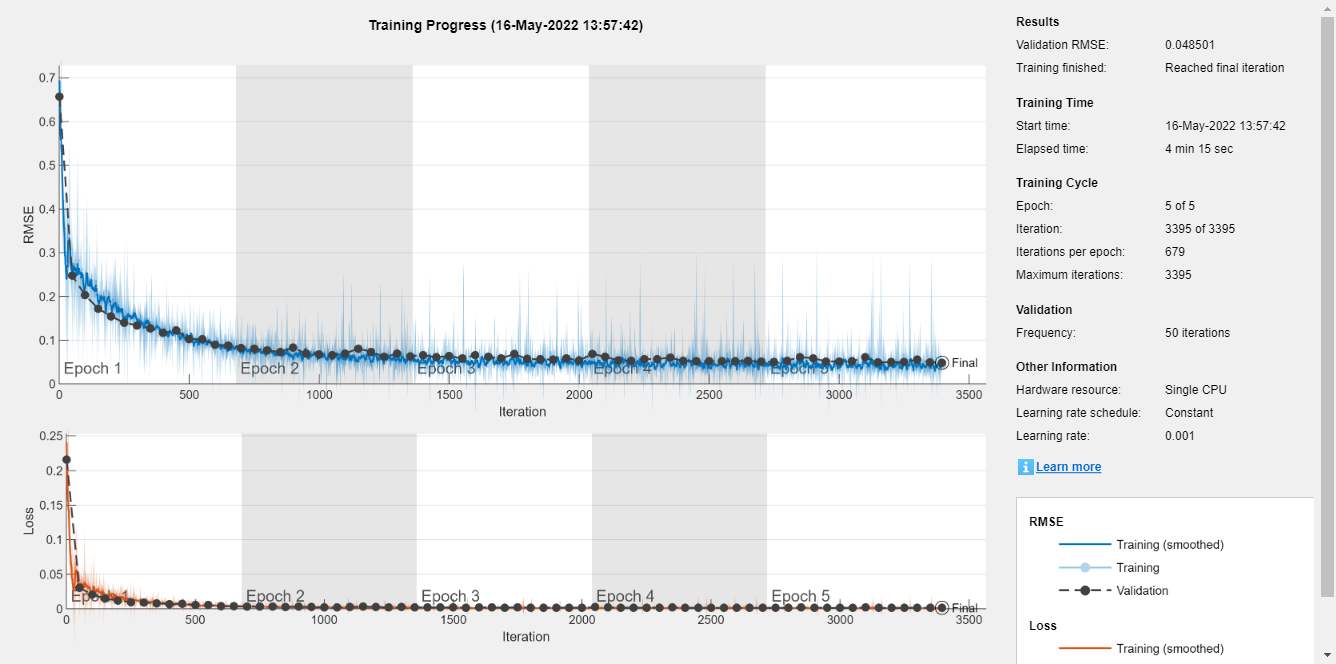

Elapsed time is 278.613242 seconds.


layerCNN2_2 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];

tic
netCNN2_2 = trainNetwork(Traintbl, layerCNN2_1, options);
toc

layerCNN1_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
%     sequenceInputLayer(input_size)
%     convolution1dLayer(filterSize,numFilters)
%     reluLayer
%     globalMaxPooling1dLayer
%     fullyConnectedLayer(numFCN)
%     %softmaxLayer
%     regressionLayer();]
tic
netCNN1_1 = trainNetwork(Traintbl, layerCNN1_1, options);
toc

%%%% 시간이 오래 걸린다. 
%{
layerCNN2_3 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
tic
netCNN2_3 = trainNetwork(Traintbl, layerCNN2_3, options);
toc

layerCNN2_4 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
     reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
tic
netCNN2_4 = trainNetwork(Traintbl, layerCNN2_4, options);
toc


figure
plot(xnorm_Ic_SOH')
xlabel("Qc")
title("Training Observation 1")
numFeatures = size(xnorm_Ic_SOH,1);
legend("Feature " + string(1:numFeatures),Location="northeastoutside")
%}
%%%%%%%%%%%%%%

save('ryan3_model_Ic_SOH.mat','netCNN2_1' ,'-append')
save('ryan3_model_Ic_SOH.mat','netCNN2_2' ,'-append')
%save('ryan3_model_Ic_SOH.mat','netCNN2_3' ,'-append')
%save('ryan3_model_Ic_SOH.mat','netCNN2_4' ,'-append')
save('ryan3_model_Ic_SOH.mat','netCNN1_1' ,'-append')

end


cellx = num2cell(xnorm_Ic_SOH(idxTestAll, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, cc_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN2_1 = predict(netCNN2_1, x_4d);
pCNN2_2 = predict(netCNN2_2, x_4d);
%pCNN2_3 = predict(netCNN2_3, x_4d);
%pCNN2_4 = predict(netCNN2_4, x_4d);
pCNN1_1 = predict(netCNN1_1, x_4d);



ytest = ynorm_SOH(idxTestAll, :)*yrate_SOH + ymin_SOH;
pCNN2_1_hat = pCNN2_1 * yrate_SOH + ymin_SOH;
pCNN2_2_hat = pCNN2_2 * yrate_SOH + ymin_SOH;
%pCNN2_3_hat = pCNN2_3 * yrate_SOH + ymin_SOH;
%pCNN2_4_hat = pCNN2_4 * yrate_SOH + ymin_SOH;
pCNN1_1_hat = pCNN1_1 * yrate_SOH + ymin_SOH;


rmse_pCNN2_1_hat = sqrt(mean(( ytest' - pCNN2_1_hat' ).^2))

rmse_pCNN2_1_hat = single
0.0040

rmse_pCNN2_2_hat = sqrt(mean(( ytest' - pCNN2_2_hat' ).^2))

rmse_pCNN2_2_hat = single
0.0051

%rmse_pCNN2_3_hat = sqrt(mean(( ytest' - pCNN2_3_hat' ).^2))
%rmse_pCNN2_4_hat = sqrt(mean(( ytest' - pCNN2_4_hat' ).^2))
rmse_pCNN1_1_hat = sqrt(mean(( ytest' - pCNN1_1_hat' ).^2))

rmse_pCNN1_1_hat = single
0.0069

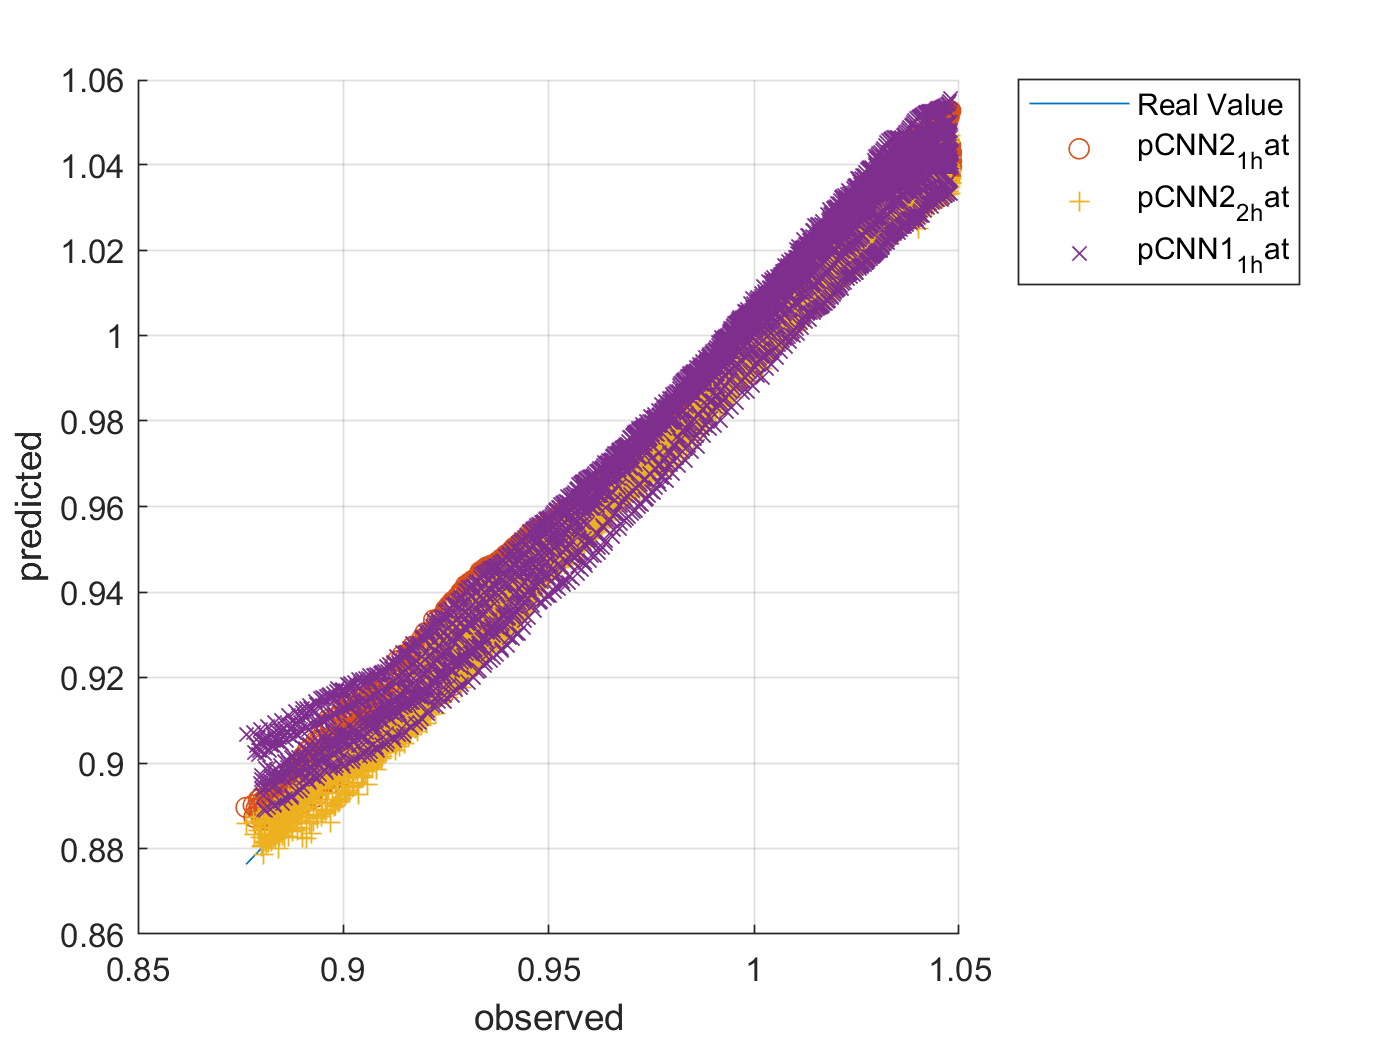




figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pCNN2_1_hat,'o')
plot(ytest,pCNN2_2_hat,'+')
%plot(ytest,pCNN2_3_hat,'*')
%plot(ytest,pCNN2_4_hat,'.')
plot(ytest,pCNN1_1_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_hat', ... 
		'pCNN2_2_hat', ...
		'pCNN1_1_hat','Location','northeastoutside')






cellx_self = num2cell(xnorm_Ic_SOH([idxTrainAll idxValidAll], :)', 1)';
cellx_self = cellfun(@transpose, cellx_self, 'UniformOutput', false);
tbl_self = table(cellx_self);

x_4d_self = zeros(1, cc_input_size, 1, height(tbl_self));
for i = 1:height(tbl_self)
    x_4d_self(:,:,:,i) = tbl_self.cellx_self{i};
end

pCNN2_1_self = predict(netCNN2_1, x_4d_self);
pCNN2_2_self = predict(netCNN2_2, x_4d_self);
%pCNN2_3_self = predict(netCNN2_3, x_4d_self);
%pCNN2_4_self = predict(netCNN2_4, x_4d_self);
pCNN1_1_self = predict(netCNN1_1, x_4d_self);

ytrain_self = ynorm_SOH([idxTrainAll idxValidAll], :)*yrate_SOH + ymin_SOH;
pCNN2_1_self_hat = pCNN2_1_self * yrate_SOH + ymin_SOH;
pCNN2_2_self_hat = pCNN2_2_self * yrate_SOH + ymin_SOH;
%pCNN2_3_self_hat = pCNN2_3_self * yrate_SOH + ymin_SOH;
%pCNN2_4_self_hat = pCNN2_4_self * yrate_SOH + ymin_SOH;
pCNN1_1_self_hat = pCNN1_1_self * yrate_SOH + ymin_SOH;


rmse_pCNN2_1_self_hat = sqrt(mean(( ytrain_self' - pCNN2_1_self_hat' ).^2))

rmse_pCNN2_1_self_hat = single
0.0053

rmse_pCNN2_2_self_hat = sqrt(mean(( ytrain_self' - pCNN2_2_self_hat' ).^2))

rmse_pCNN2_2_self_hat = single
0.0064

%rmse_pCNN2_3_self_hat = sqrt(mean(( ytrain_self' - pCNN2_3_self_hat' ).^2))
%rmse_pCNN2_4_self_hat = sqrt(mean(( ytrain_self' - pCNN2_4_self_hat' ).^2))
rmse_pCNN1_1_self_hat = sqrt(mean(( ytrain_self' - pCNN1_1_self_hat' ).^2))

rmse_pCNN1_1_self_hat = single
0.0076

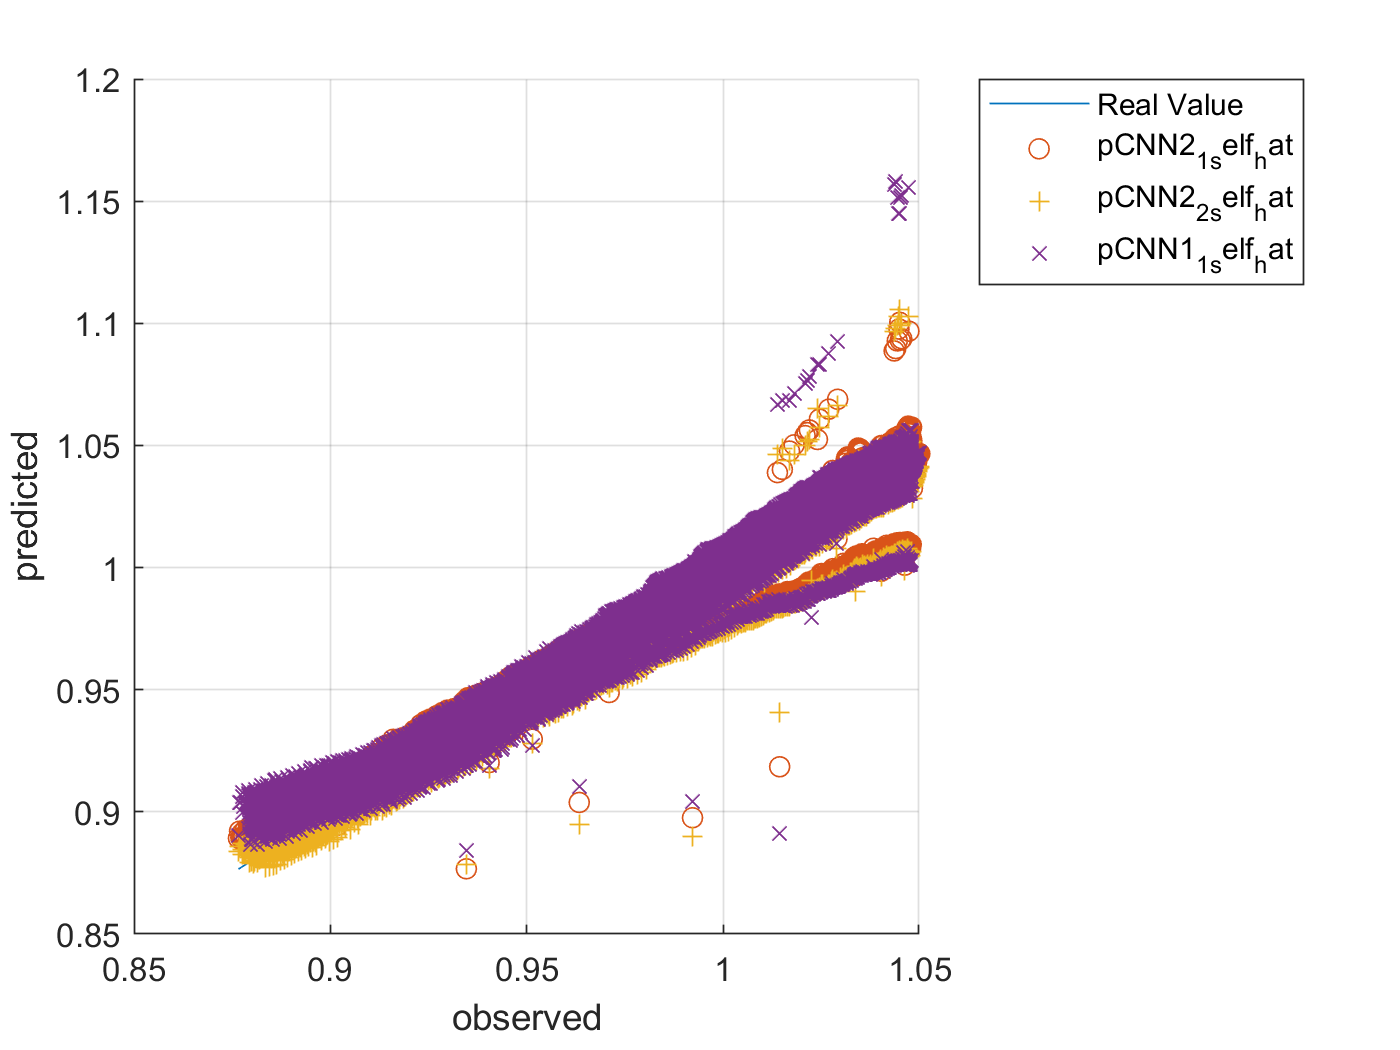




figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pCNN2_1_self_hat,'o')
plot(ytrain_self,pCNN2_2_self_hat,'+')
%plot(ytrain_self,pCNN2_3_self_hat,'*')
%plot(ytrain_self,pCNN2_4_self_hat,'.')
plot(ytrain_self,pCNN1_1_self_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_self_hat', ... 
		'pCNN2_2_self_hat', ...
		'pCNN1_1_self_hat','Location','northeastoutside')

# LSTM

- LSTM : 1 lstm layer with 5 hidden units

cc_input_size = 20;
numHiddenUnits = 50;

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |         0.63 |         0.64 |       0.2003 |       0.2044 |          0.0010 |
|       1 |          50 |       00:00:08 |         0.25 |         0.22 |       0.0321 |       0.0254 |          0.0010 |
|       1 |         100 |       00:00:13 |         0.24 |         0.21 |       0.0291 |       0.0223 |          0.0010 |
|       1 |         150 |       00:00:18 |         0.25 |         0.20 |       0.0320 |       0.0192 |          0.0010 |
|       

Elapsed time is 159.844412 seconds.


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |         0.77 |         0.72 |       0.2937 |       0.2624 |          0.0010 |
|       1 |          50 |       00:00:16 |         0.21 |         0.23 |       0.0226 |       0.0260 |          0.0010 |
|       1 |         100 |       00:00:21 |         0.24 |         0.22 |       0.0291 |       0.0237 |          0.0010 |
|       1 |         150 |       00:00:27 |         0.27 |         0.20 |       0.0361 |       0.0203 |          0.0010 |
|       

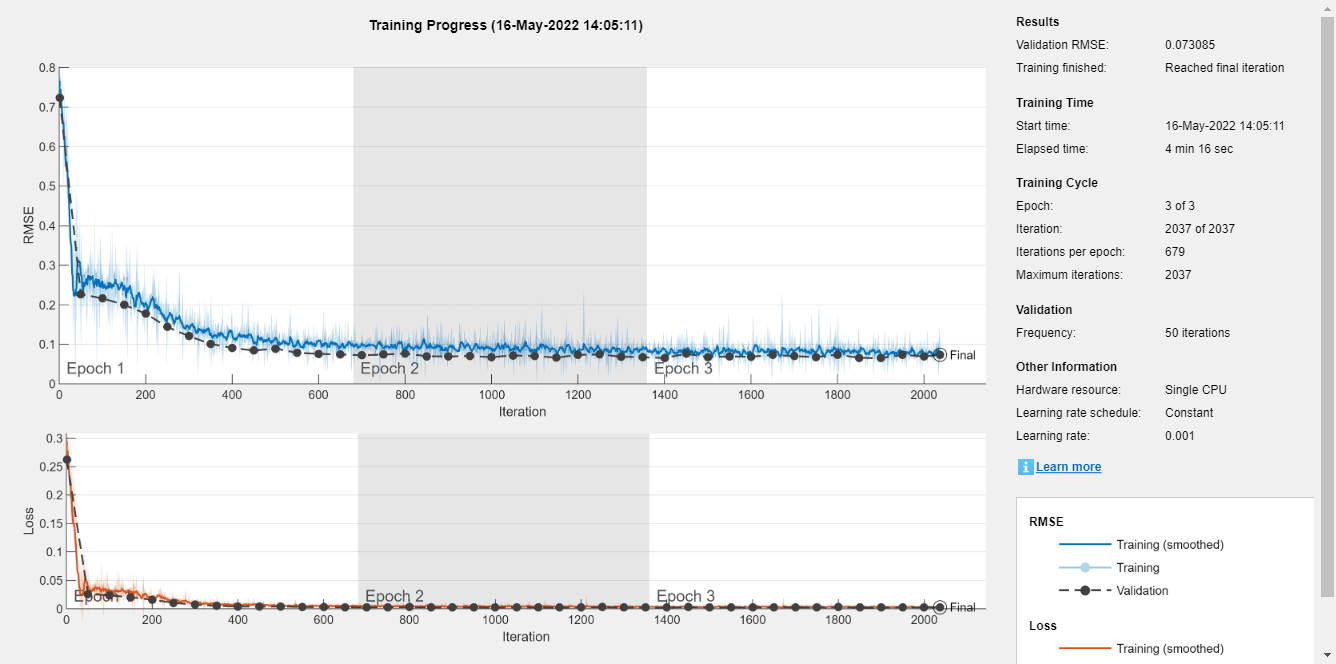

Elapsed time is 274.765536 seconds.



if generate_model
layersLSTM = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

layersLSTM2 = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(xnorm_Ic_SOH', 1)';
cellyB = num2cell(ynorm_SOH);

traincellx = cellx(idxTrainAll, :);
valcellx = cellx(idxValidAll, :);
testcellx = cellx(idxTestAll, :);

traincellyB = cellyB(idxTrainAll, :);
valcellyB = cellyB(idxValidAll, :);
testcellyB = cellyB(idxTestAll, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',epoc_count_lstm, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

tic
netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);
toc 

tic
netLSTM2 = trainNetwork(traincellx, traincellyB, layersLSTM2, options);
toc

save('ryan3_model_Ic_SOH.mat','netLSTM' ,'-append')
save('ryan3_model_Ic_SOH.mat','netLSTM2' ,'-append')

end


pLSTM = cell2mat(predict(netLSTM, num2cell(xnorm_Ic_SOH(idxTestAll, :)', 1)));
pLSTM2 = cell2mat(predict(netLSTM2, num2cell(xnorm_Ic_SOH(idxTestAll, :)', 1)));
ytest = ynorm_SOH(idxTestAll, :)*yrate_SOH + ymin_SOH;
pLSTM_hat = pLSTM * yrate_SOH + ymin_SOH;
pLSTM2_hat = pLSTM2 * yrate_SOH + ymin_SOH;
rmse_pLSTM_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM_hat = single
0.0093

rmse_pLSTM2_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM2_hat = single
0.0093

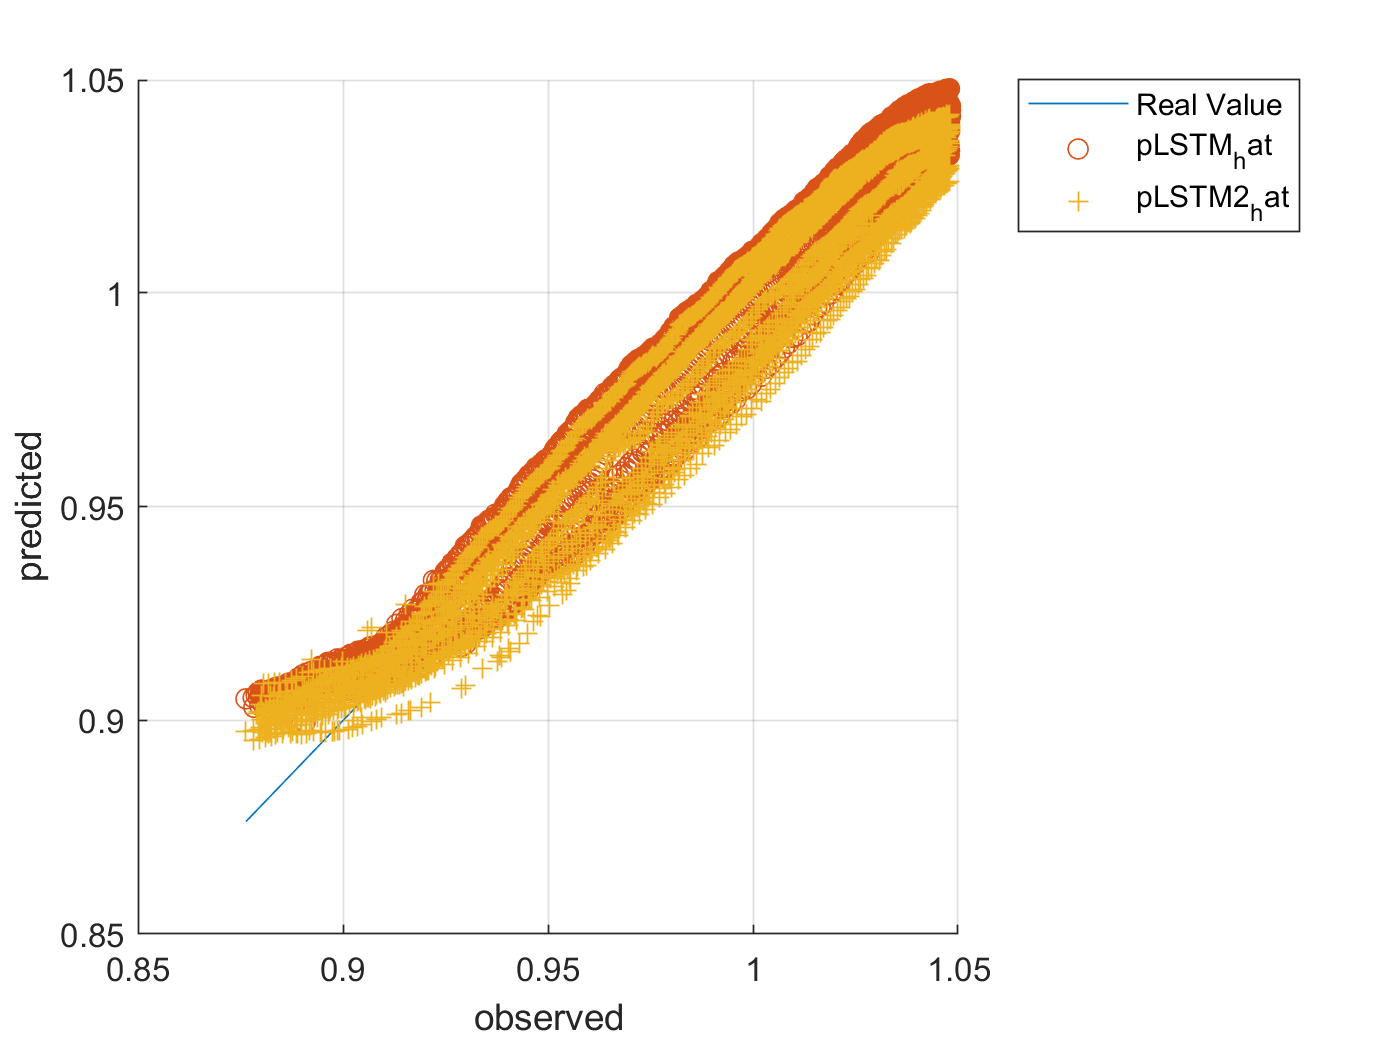



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pLSTM_hat,'o')
plot(ytest,pLSTM2_hat,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_hat', ...
        'pLSTM2_hat','Location','northeastoutside')



pLSTM_self = cell2mat(predict(netLSTM, num2cell(xnorm_Ic_SOH([idxTrainAll idxValidAll], :)', 1)));
pLSTM2_self = cell2mat(predict(netLSTM2, num2cell(xnorm_Ic_SOH([idxTrainAll idxValidAll], :)', 1)));
ytrain_self = ynorm_SOH([idxTrainAll idxValidAll], :)*yrate_SOH + ymin_SOH;
pLSTM_self = pLSTM_self * yrate_SOH + ymin_SOH;
pLSTM2_self = pLSTM2_self * yrate_SOH + ymin_SOH;
rmse_pLSTM_self_hat = sqrt(mean(( ytrain_self' - pLSTM_self' ).^2))

rmse_pLSTM_self_hat = single
0.0099

rmse_pLSTM2_self_hat = sqrt(mean(( ytrain_self' - pLSTM2_self' ).^2))

rmse_pLSTM2_self_hat = single
0.0110

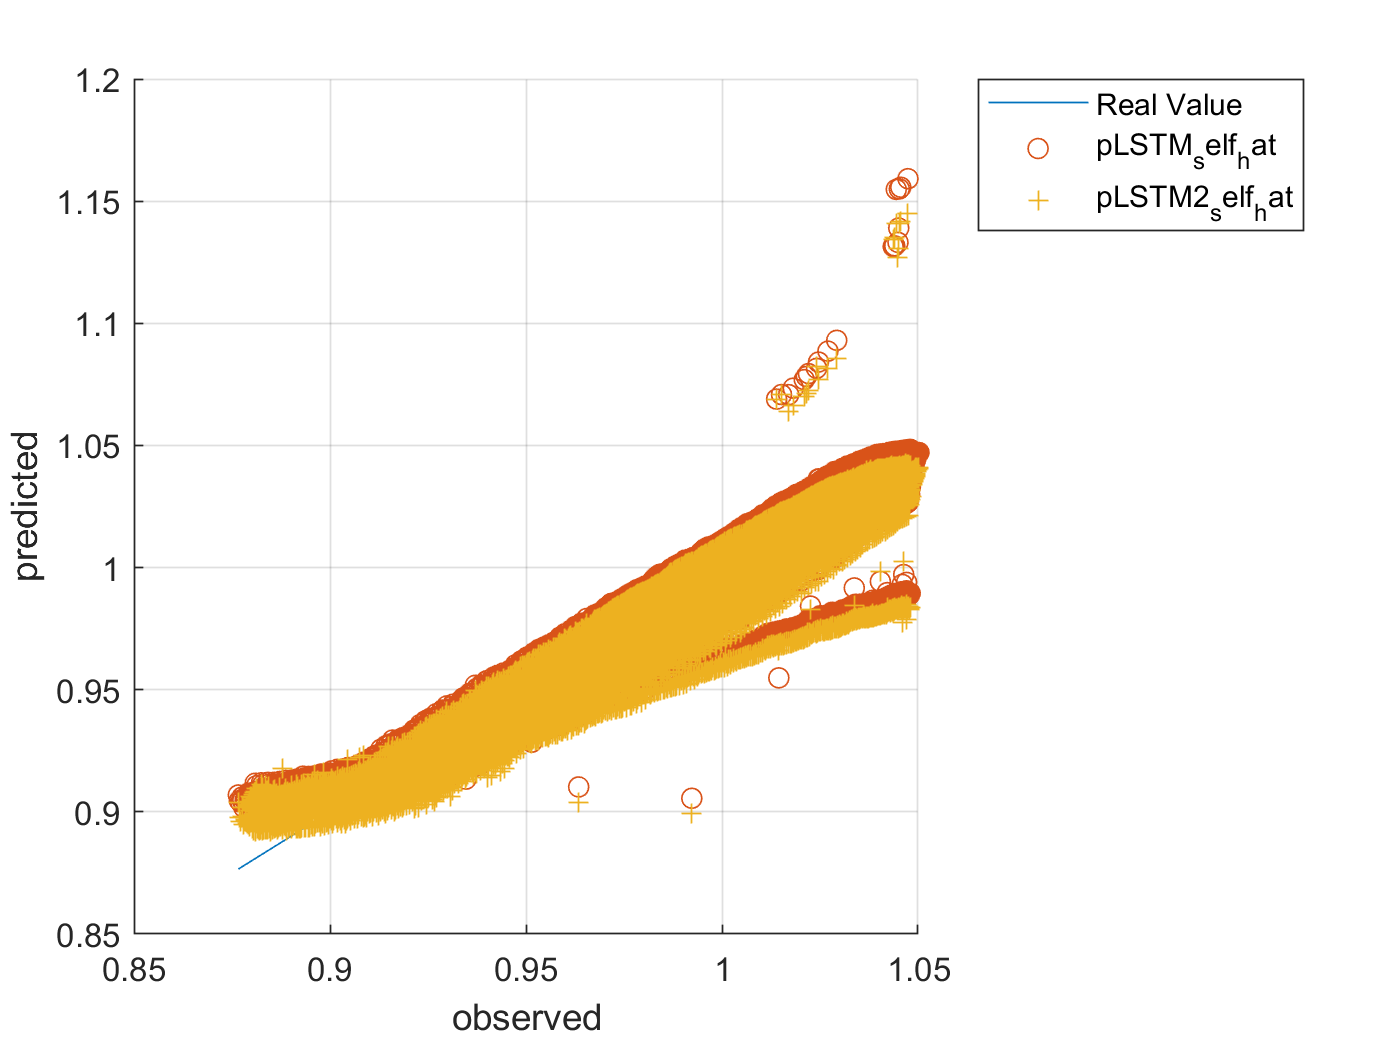


figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pLSTM_self,'o')
plot(ytrain_self,pLSTM2_self,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_self_hat', ...
        'pLSTM2_self_hat','Location','northeastoutside')